# **drawLine**

Draw the line between two points

## Description

 Parametric equations of the line are

$x=x_1 +t\left(x_2 -x_1 \right)$,      $y=y_1 +t\left(y_2 -y_1 \right)$,    $t_1 \le t{\le t}_2$.

where *r *is radius.

## Syntax

drawLine( x1, y1, x2, y2)

drawLine( x1, y1, x2, y2, t1, t2)

drawLine( x1, y1, x2, y2,LineSpec)

drawLine( x1, y1, '-rtheta',r,th)

drawLine( x1, y1, '-delta',dx,dy)

p = drawLine(__)

## Description

drawLine( x1, y1, x2, y2) draw the line betwe two points using current line specification. 

drawLine( x1, y1, x2, y2, t1, t2) draw the line betwe two points from point given by t1 to point given by t2

drawLine( x1, y1, x2, y2,LineSpec)  sets the line style, line width, and color.

drawLine( x1, y1, '-polar',r,th) draw line from start point to point given by polar coordinates from start point.

drawLine( x1, y1, '-delta',dx,dy) draw line from start point to point given by shift vector from start point.

p = drawLine(__) returns structure with input and output parameters of the line.

## Method

For calculation of the coordinates of the line **drawLine **use **evalLine( x1,y1,x2,y2,t)  **which returns coordinates *x *and *y *of the curve at given parameter t . For usage of **evalLine **see Example 2.

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**x1, y1 - **start point (real scalar)

**x2, y2 - **end point (real scalar)

or instaed of x2,y2

**'-rtheta',r,th **- polar coordinates of end point from start point

or

**'-delta',dx,dy **- shift vector

### **Optonal Input Arguments**

**t1,t2** - start and end parameter (defaults are 0 and 1)

### Optional Name-Value Pair Input Arguments

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with the fields

- p.xk, p.yk - key points: 1=start,2=end,3=center

- p.color - line color

## Examples

### Example 1

%Data 
x1 = 1; y1 = 1;
x2 = 2; y2 = 2;
figure
hold on
axis equal
L1 = drawLine(x1,y1,x2,y2)

L1 = struct with fields:
       x1: 1
       y1: 1
       x2: 2
       y2: 2
        d: 1.4142
    style: '-'
    width: 0.5000
    color: [0 0.4470 0.7410]


scatter(x1,y1,30,'r')
scatter(x2,y2,30,'r')
L2 = drawLine(x1,y1,x2,y2,0.2,0.7,'LineWidth',2,'Color','r')

L2 = struct with fields:
       x1: 1.2000
       y1: 1.2000
       x2: 1.7000
       y2: 1.7000
        d: 0.7071
    style: '-'
    width: 2
    color: [1 0 0]


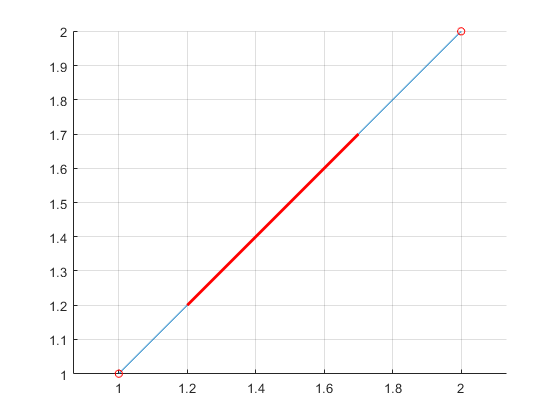

grid on

### Example 2

%Data 
x1 = 1; y1 = 1;
dx = 2; dy = 2;
figure
hold on
axis equal
L1 = drawLine(x1,y1,'-delta',dx,dy,'LineWidth',2)

L1 = struct with fields:
       x1: 1
       y1: 1
       x2: 3
       y2: 3
        d: 2.8284
    style: '-'
    width: 2
    color: [0 0.4470 0.7410]


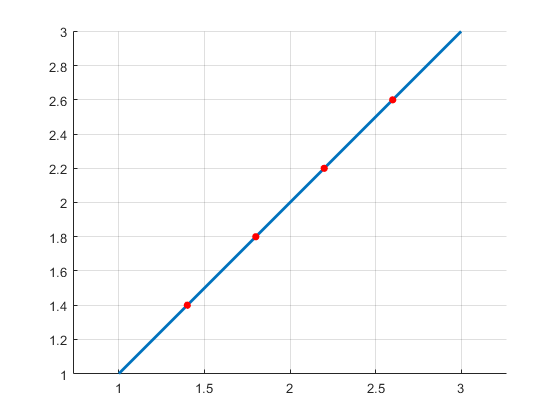

[x, y] = evalLine( L1.x1, L1.y1, L1.x2, L1.y2, [0.2,0.4,0.6,0.8]);
scatter(x,y,30,'r','filled')
grid on

### Example 3

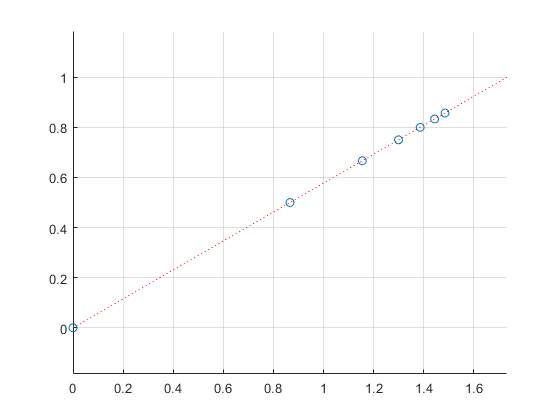

figure
hold on
axis equal
L=drawLine(0,0,'-polar',2,30,'r:');
[x,y] = evalLine(L.x1,L.y1,L.x2,L.y2,[0,1/2,2/3,3/4,4/5,5/6,6/7]);
scatter(x,y)
grid on

## **See Also**

## References